%% Import data from spreadsheet
% Script for importing data from the following spreadsheet:
%
%    Workbook: C:\Users\hp\Desktop\ProjetFIN8311 .xlsx
%    Worksheet: Faitstylisé
%
% Auto-generated by MATLAB on 14-Apr-2023 05:47:22

%% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 11);

% Specify sheet and range
opts.Sheet = "Faitstylisé";
opts.DataRange = "A3:K4829";

% Specify column names and types
opts.VariableNames = ["Date", "EEM", "RendementBrut", "RendementNet", "Logrendement", "VarName6", "Date1", "TBILL", "RendementBrut1", "RendementNet1", "Logrendement1"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double", "string", "datetime", "double", "double", "double", "double"];

% Specify variable properties
opts = setvaropts(opts, "VarName6", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "VarName6", "EmptyFieldRule", "auto");

% Import the data
data = readtable("C:\Users\hp\Desktop\ProjetFIN8311 .xlsx", opts, "UseExcel", false);


%% Clear temporary variables
clear opts

# Statistique descriptive:

Dans cette section, une analyse exploratoire des données à été étudié afin de construire une idée préliméniare sur la nature des variables toute en s'appuynt sur les statistiques de location, de dispersion ainsi que le skewenis et kurtiones:

head(data);

       Date         EEM     RendementBrut    RendementNet    Logrendement    VarName6       Date1       TBILL    RendementBrut1    RendementNet1    Logrendement1
    ___________    _____    _____________    ____________    ____________    ________    ___________    _____    ______________    _____________    _____________

    07-Mar-2023    38.74           NaN               NaN             NaN        ""       07-Mar-2023    3.94            NaN                NaN              NaN  
    06-Mar-2023     39.4       0.98325         -0.016751       -0.016893        ""       06-Mar-2023    3.91         1.0077          0.0076

date=data{:,1};
Datetime=datetime(date,'InputFormat','yyyy-mm-dd');
T=length(date);
EEM=data{:,2};
RendEEM=data{2:T,3};
TBILL=data{:,8};
RendTBILL=data{2:T,9};
rendnet_EEM=data{2:T,4};
rendnet_TBILL=data{2:T,10};
logrend_EEM=data{2:T,5};
logrend_TBILL=data{2:T,11};

**Action EEM**

formatSpec1='les statistiques relatives à laction risqué EEM sont comme suit :\n \n Moyen=%f \n \n le minimum=%f \n \n le maximum=%f \n \n le mode=%f \n \n le median=%f \n \n Ecart type= %f \n \n Variance=%f \n \n Skewness=%f \n \n kurtosis=%f';
fprintf(formatSpec1,mean(EEM),min(EEM),max(EEM),mode(EEM),median(EEM),std(EEM),var(EEM),skewness(EEM),kurtosis(EEM));

les statistiques relatives à laction risqué EEM sont comme suit :
 
 Moyen=32.579284 
 
 le minimum=11.087530 
 
 le maximum=55.536560 
 
 le mode=22.695095 
 
 le median=33.543861 
 
 Ecart type= 8.998693 
 
 Variance=80.976469 
 
 Skewness=-0.301859 
 
 kurtosis=3.081027

x=[mean(EEM),min(EEM),max(EEM),mode(EEM),median(EEM),std(EEM),var(EEM),skewness(EEM),kurtosis(EEM)];
x;

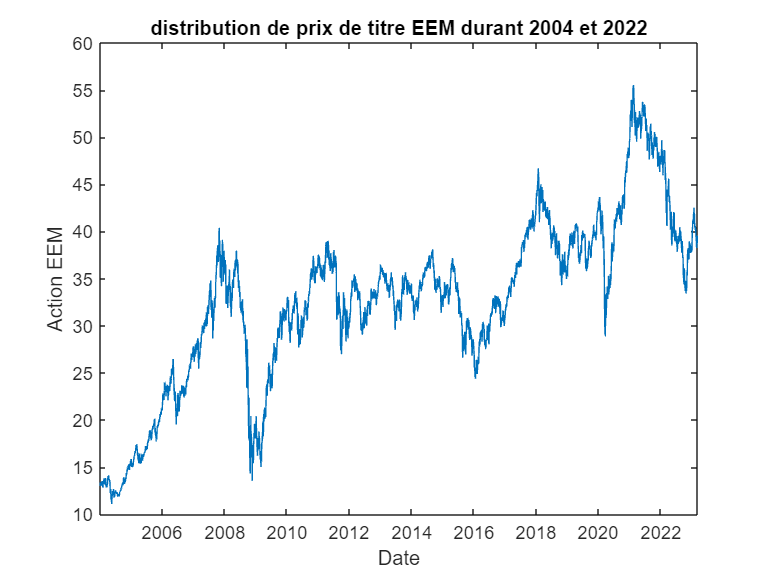

figure(1)
plot(Datetime,EEM);
ylabel('Action EEM');
xlabel("Prix titre EEM");
xlabel("Date");
title('distribution de prix de titre EEM durant 2004 et 2022');

formatSpec2='les statistiques relatives au rendement pour laction risqué EEM sont comme suit :\n \n Moyen=%f \n \n le mode=%f \n \n Ecart type= %f \n \n Variance=%f \n \n Skewness=%f \n \n kurtosis=%f\n \n median=%f';
fprintf(formatSpec2,mean(RendEEM),mode(RendEEM),std(RendEEM),var(RendEEM),skewness(RendEEM),kurtosis(RendEEM),kurtosis(RendEEM));

les statistiques relatives au rendement pour laction risqué EEM sont comme suit :
 
 Moyen=1.000388 
 
 le mode=1.000000 
 
 Ecart type= 0.017999 
 
 Variance=0.000324 
 
 Skewness=0.512551 
 
 kurtosis=20.314920
 
 median=20.314920

Durant l'horizon ou la période du calcul , l'action EEM a un moyen de rendement de 0.00392 avec une variance de 0.0003 

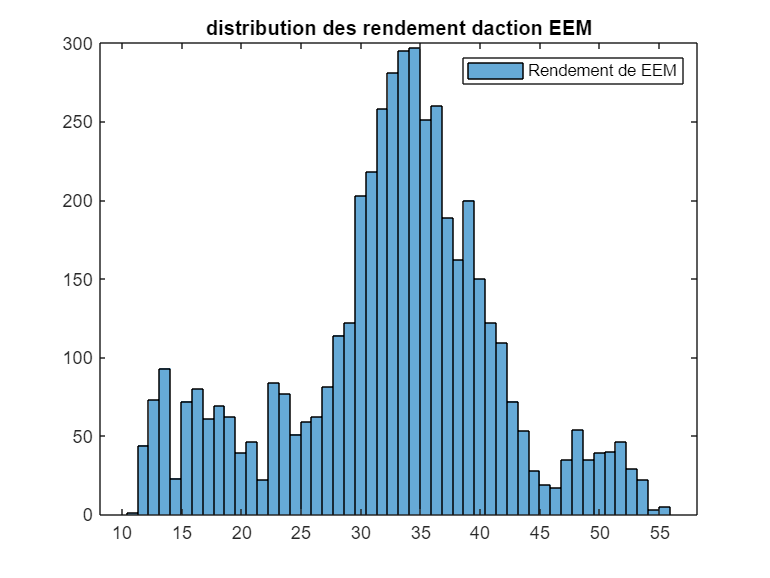

figure(2)
histogram(EEM,50);
legend('Rendement de EEM');
title('distribution des rendement daction EEM');

**Action TBILL**

formatSpec3='les statistiques relatives au laction sans risque TBILL sont comme suit :\n \n Moyen=%f \n \n  le mode=%f \n \n  Ecart type= %f \n \n  Variance=%f \n \n Skewness=%f \n \n  kurtosis=%f';
fprintf(formatSpec3,mean(TBILL),mode(TBILL),std(TBILL),var(TBILL),skewness(TBILL),kurtosis(TBILL));

les statistiques relatives au laction sans risque TBILL sont comme suit :
 
 Moyen=2.854601 
 
  le mode=2.330000 
 
  Ecart type= 1.122634 
 
  Variance=1.260306 
 
 Skewness=0.194691 
 
  kurtosis=2.144152

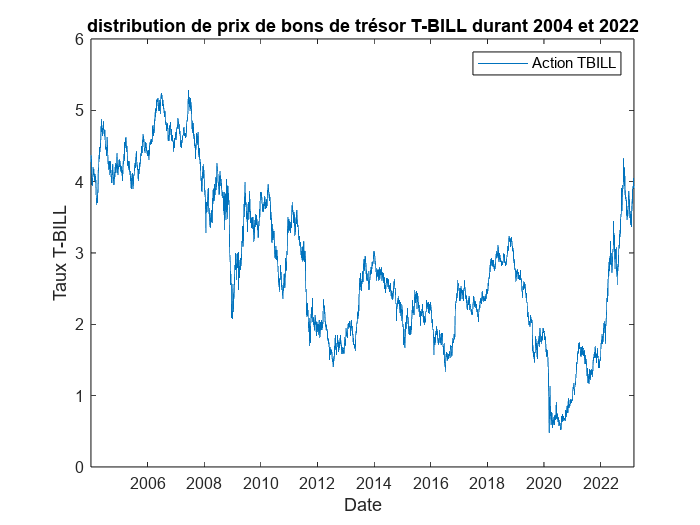


figure(3)
plot(Datetime,TBILL);
legend('Action TBILL');
xlabel('Date');
ylabel("Taux T-BILL");
title('distribution de prix de bons de trésor T-BILL durant 2004 et 2022');


formatSpec3='les statistiques relatives au rendement pour laction sans risque TBILL sont comme suit :\n \n Moyen=%f \n \n le mode=%f \n \n Ecart type= %f \n \n Variance=%f \n \n Skewness=%f \n \n kurtosis=%f';
fprintf(formatSpec3,mean(RendTBILL),mode(RendTBILL),std(RendTBILL),var(RendTBILL),skewness(RendTBILL),kurtosis(RendTBILL));

les statistiques relatives au rendement pour laction sans risque TBILL sont comme suit :
 
 Moyen=1.000338 
 
 le mode=1.000000 
 
 Ecart type= 0.026684 
 
 Variance=0.000712 
 
 Skewness=0.863341 
 
 kurtosis=37.660019

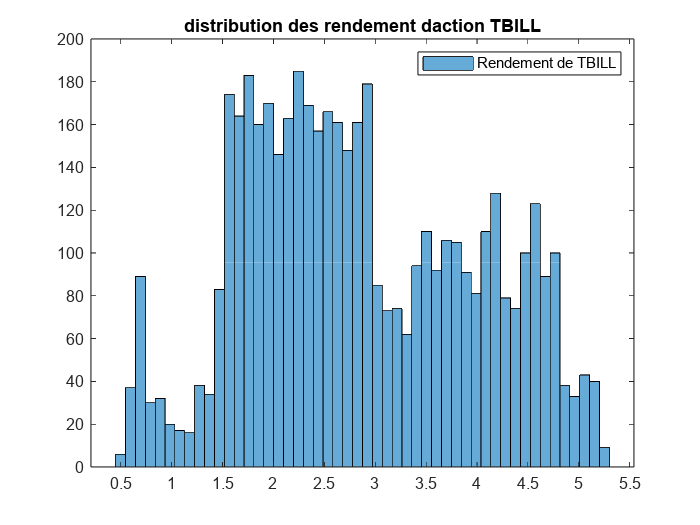


figure(4)
histogram(TBILL,50);
legend('Rendement de TBILL');
title('distribution des rendement daction TBILL');

## test de stationnarité

% test stationarité Rendement Rendement EEM
[Hdf_EEM,Pdf_EEM,STATdf_EEM,CV_EEM]=adftest(RendEEM);
formatSpec4='le résultat du test de Dickey-fuller pour lhypothèse de stationnarité  pour les rendement EEM  :\n \n Logical=%f \n \n p-value=%f \n \n Stat= %f \n \n Cvalue=%f \n \n ';
fprintf(formatSpec4,[Hdf_EEM,Pdf_EEM,STATdf_EEM,CV_EEM])

le résultat du test de Dickey-fuller pour lhypothèse de stationnarité  pour les rendement EEM  :
 
 Logical=0.000000 
 
 p-value=0.318398 
 
 Stat= -0.910671 
 
 Cvalue=-1.941600 
 
 

D'aprés le résult de ce test on constate que l'hypothèse stipulant sur la stationnarité de la serie des rendements EEM au fil de temps est significativement rejetée ( logical=1 , p-value=0.001 <0.05).

[Hdf_TBILL,Pdf_TBILL,STATdf_TBILL,CV_TBILL]=adftest(RendTBILL);
formatSpec5='le résultat du test de Dickey-fuller pour lhypothèse de stationnarité  pour les rendement TBILL  :\n \n Logical=%f \n \n p-value=%f \n \n Stat= %f \n \n Cvalue=%f \n \n  ';
fprintf(formatSpec5,[Hdf_TBILL,Pdf_TBILL,STATdf_TBILL,CV_TBILL]);

le résultat du test de Dickey-fuller pour lhypothèse de stationnarité  pour les rendement TBILL  :
 
 Logical=0.000000 
 
 p-value=0.173533 
 
 Stat= -1.319222 
 
 Cvalue=-1.941600 
 
  

On constate que l'hypothèse de stationarité des rendements de T-BILL est accepté mais pas significativement puisque le p-value est de 0.38>0.05.

## test de normalité :

#### -Histogramme des rendements avec la courbe de la loi normale tracée par-dessus

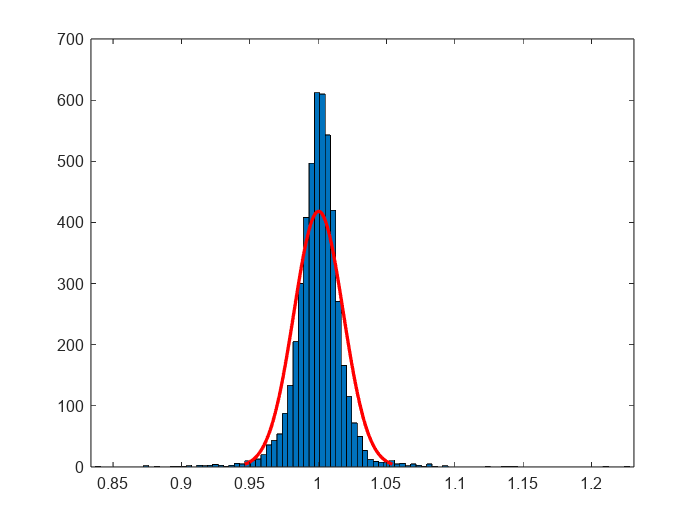

figure(5);
histfit(RendEEM,100);

#### -QQ-plot:

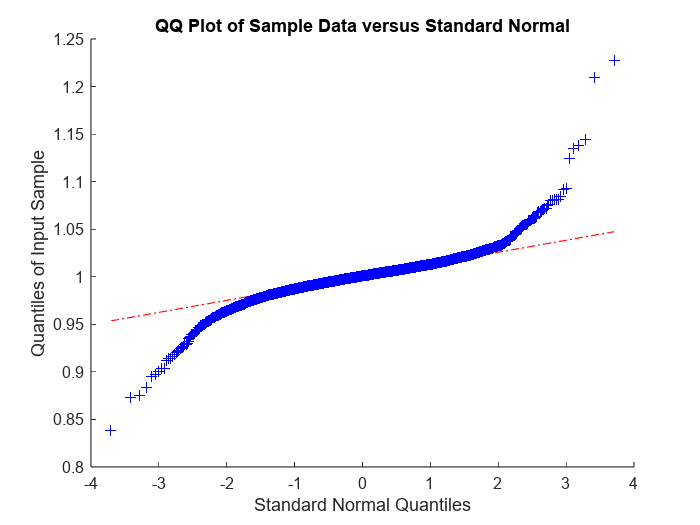

figure(6);
qqplot(RendEEM);

#### -Test de Kolmogorov-Smirnov

% test nomrality Rendement de l'action EEM
[H_EEM,P_EEM,KSSTAT_EEM,CV_EEM]=kstest(RendEEM);
formatSpec6='le résultat du test dhypothèse de la nomalité  pour les rendement EEM  :\n \n Logical=%f \n \n p-value=%f \n \n Stat= %f \n \n Cvalue=%f \n \n' ;
fprintf(formatSpec6,[H_EEM,P_EEM,KSSTAT_EEM,CV_EEM]);

le résultat du test dhypothèse de la nomalité  pour les rendement EEM  :
 
 Logical=1.000000 
 
 p-value=0.000000 
 
 Stat= 0.820394 
 
 Cvalue=0.019515 
 


#### -Test de normalité de Jarque Bera

% test nomrality des Rendement de l'action EEM
alpha=0.05; % seuil du test
[Hj_EEM,Pj_EEM,KSSTATj_EEM,CVj_EEM]=jbtest(EEM,alpha);

formatSpec6='le résultat du test dhypothèse de la nomalité  pour EEM  :\n \n Logical=%f \n \n p-value=%f \n \n Stat= %f \n \n Cvalue=%f \n \n' ;
fprintf(formatSpec6,[Hj_EEM,Pj_EEM,KSSTATj_EEM,CVj_EEM]);

le résultat du test dhypothèse de la nomalité  pour EEM  :
 
 Logical=1.000000 
 
 p-value=0.001000 
 
 Stat= 74.625813 
 
 Cvalue=5.980559 
 


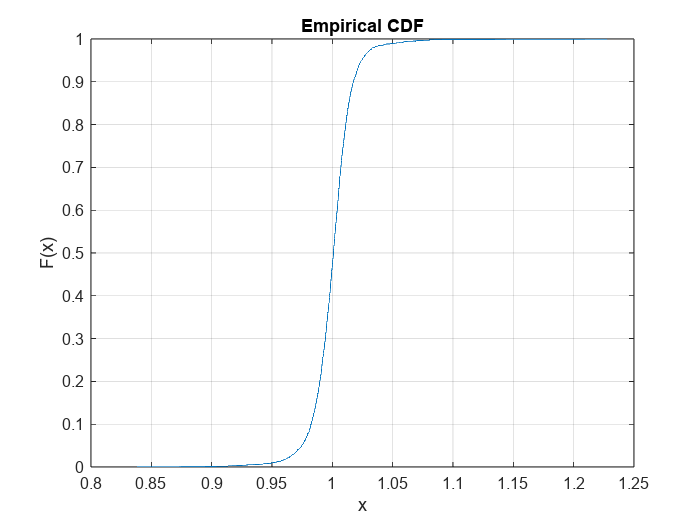

H_EEM =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-Inf 0.8383 0.8383 0.8727 0.8727 0.8752 0.8752 0.8832 0.8832 0.8947 0.8947 0.8968 0.8968 0.8999 0.8999 0.9037 0.9037 0.9040 0.9040 0.9124 0.9124 0.9136 0.9136 0.9136 0.9136 0.9166 0.9166 0.9187 0.9187 0.9203 0.9203 0.9215 0.9215 … ]
              YData: [0 0 2.0721e-04 2.0721e-04 4.1442e-04 4.1442e-04 6.2163e-04 6.2163e-04 8.2884e-04 8.2884e-04 0.0010 0.0010 0.0012 0.0012 0.0015 0.0015 0.0017 0.0017 0.0019 0.0019 0.0021 0.0021 0.0023 0.0023 0.0025 0.0025 0.0027 0.0027 0.0029 … ]

  Show 

figure(1)
H_EEM = cdfplot(RendEEM)

% test nomrality des Rendement de l'action T-BILL
[H,P,KSSTAT,CV]=jbtest(TBILL);

formatSpec='\n le résultat du test dhypothèse de la normalité pour T-BILL :\n \n Logical=%f \n \n p-value=%f \n \n Stat= %f \n \n Cvalue=%f';
fprintf(formatSpec,[H,P,KSSTAT,CV]);


 le résultat du test dhypothèse de la normalité pour T-BILL :
 
 Logical=1.000000 
 
 p-value=0.001000 
 
 Stat= 177.813539 
 
 Cvalue=5.980559

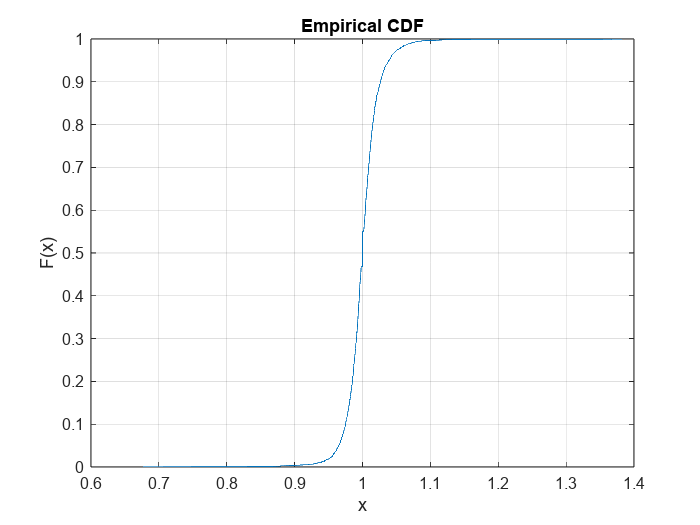

figure(2)
D= cdfplot(RendTBILL);

%Etude de correlation entre le taux T-BILL et le prix de titre EEM:
corrcoef(EEM,TBILL)

ans =     1.0000   -0.5997
   -0.5997    1.0000


## Modélisation des écart type:

**Consitution des rendement des portefeuille:**

weight=0.0129

weight = 0.0129

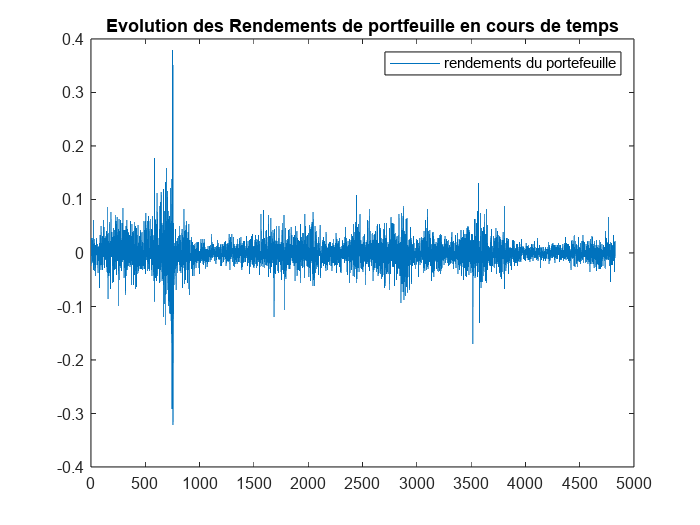

rend_port=0.0129*rendnet_EEM+(1-weight)*rendnet_TBILL;
plot(rend_port);
legend("rendements du portefeuille");
title("Evolution des Rendements de portfeuille en cours de temps");

#### -Test de normalité de Jarque Bera pour les rendement de portefeuille:

% test nomrality des Rendement de l'action EEM
alpha=0.05; % seuil du test
[Hj_p,Pj_p,KSSTATj_p,CVj_p]=jbtest(rend_port);

formatSpec='\n le résultat du test dhypothèse de la normalité pour les rendements de portefuille :\n \n Logical=%f \n \n p-value=%f \n \n Stat= %f \n \n Cvalue=%f';
fprintf(formatSpec,[Hj_p,Pj_p,KSSTATj_p,CVj_p]);


 le résultat du test dhypothèse de la normalité pour les rendements de portefuille :
 
 Logical=1.000000 
 
 p-value=0.001000 
 
 Stat= 241536.113519 
 
 Cvalue=5.980557

## test de stationnarité

% test stationarité Rendement Rendement EEM
[Hdf_p,Pdf_p,STATdf_p,CV_p]=adftest(rend_port);
formatSpec4='le résultat du test de Dickey-fuller pour lhypothèse de stationnarité  pour les rendement portefeuille  :\n \n Logical=%f \n \n p-value=%f \n \n Stat= %f \n \n Cvalue=%f \n \n ';
fprintf(formatSpec4,[Hdf_p,Pdf_p,STATdf_p,CV_p])

le résultat du test de Dickey-fuller pour lhypothèse de stationnarité  pour les rendement portefeuille  :
 
 Logical=1.000000 
 
 p-value=0.001000 
 
 Stat= -71.077234 
 
 Cvalue=-1.941600 
 
 

**Modèle Garch :**

% Model Garch pour les log rendement 
Mdl1=garch('GARCHLags',1,'ARCHLags',1);
Estmdl1=estimate(Mdl1,rend_port);

 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    1.1786e-06      5.159e-07        2.2846        0.022337
    GARCH{1}       0.93823      0.0041307        227.13               0
    ARCH{1}       0.061767      0.0041648        14.831      9.3003e-50



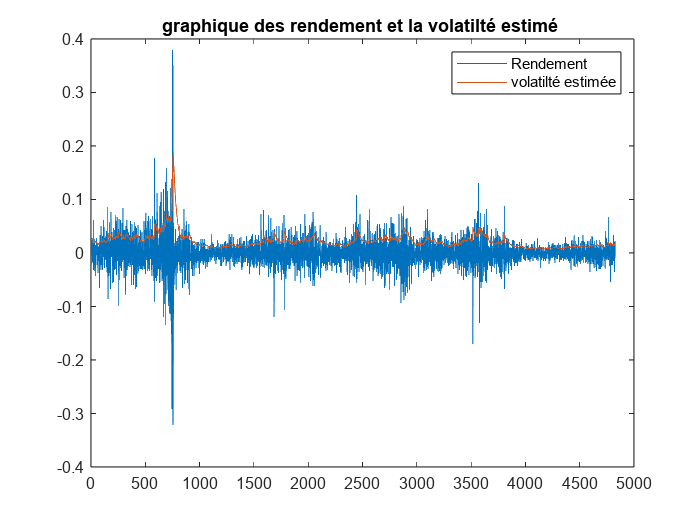

Condvar=infer(Estmdl1,rend_port);
Condvol=sqrt(Condvar);
figure(7)
plot(rend_port); hold on;
plot(Condvol); hold off;
title("graphique des rendement et la volatilté estimé ");
legend("Rendement","volatilté estimée");

% Model Garch pour les log rendement 
Mdl2=garch('GARCHLags',1,'ARCHLags',1);
Mdl2.Distribution = "t";

Estmdl2=estimate(Mdl2,rend_port);

 
    GARCH(1,1) Conditional Variance Model (t Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    4.5709e-06      1.236e-06        3.6981      0.00021726
    GARCH{1}        0.9034       0.009334        96.786               0
    ARCH{1}       0.096599       0.010973         8.803      1.3319e-18
    DoF             5.1354        0.46929        10.943      7.1741e-28



Condvar2=infer(Estmdl2,rend_port);
Condvol2=sqrt(Condvar);
figure(8)
plot(rend_port); hold on;
plot(Condvol2); hold off;
title("graphique des rendement et la volatilté estimé ");
legend("Rendement","volatilté estimée");